# **VALIDATE:   **the Brain derived 7-dof car model against a Simscape model

 **NOTE:**

- The Brain derived model made the assumption of **Small angles** for the car's PITCH and ROLL angles. (eg:   $L_f \ldotp \sin \left(\theta \right)\approx L_f \ldotp \theta$ )

- The Simscape model does **NOT** make this Small angle assumption.

- So ? - So, we expect that provided the PITCH and ROLL angles are small we should get good agreement between the two models.

`Bradley Horton : 08-Aug-2021, bhorton@mathworks.com`

## Read the car parameters

Our car parameters are defined in  an EXCEL file [`bh_7dof_car_database.xlsx`](matlab:  winopen("bh_7dof_car_database.xlsx"))`.`  The data sheets called **"PARAMS_SET_VALIDATE"** and **"IC_SET_VALIDATE"**   contain vehicle and Initial Condition data that we'll use for comparing the Brain and Simscape models

OBJ_car_params =  bh_7dof_car_database_CLS("bh_7dof_car_database.xlsx", "PARAMS_SET_VALIDATE", "IC_SET_VALIDATE");

The table below lists the parameters that we'll use in our simulation.  

- **NOTE:** the small values for the damping co-efficients $c_{\textrm{bR}} \;,c_{\textrm{fR}} \;,\;\ldotp \ldotp \ldotp \ldotp c_{\textrm{bRG}} \;,\ldotp \ldotp \ldotp$ etc

OBJ_car_params.car_tab

ans = 29×4 table
              Name      Value     Units                     Description                
             _______    _____    ________    __________________________________________

    m_c      "m_c"      1500     "kg"        "Mass of car body"                        
    I_cZ     "I_cZ"     1000     "kg.m^2"    "Inertia (Z-axis) of car body"            
    I_cX     "I_cX"      600     "kg.m^2"    "Inertia (X-axis) of car body"            
    m_bR     "m_bR"       80     "kg"        "Mass of back RIGHT wheel and suspension" 
    m_fR     "m_fR"      100     "kg"        "Mass of front RIGHT wheel and suspension"
    m_bL     "m_bL"       80     "kg"        "Mass of back LEFT wheel and suspension"  
    m_fL     "m_fL"    

Note also that the system** Initial Conditions** are defined in the `IC_pos` property.  The order of the DOF vector is:

- `          1      2     3     4      5      6      7`

- `      [ y_c,  theta,  psi,   y_bR,  y_fR,  y_bL,  y_fL ]`

OBJ_car_params.IC_pos'

ans =     0.4000    0.1800    0.2500   -0.2000    0.3000    0.1500    0.1000


## Open the Simulink file and run the model

The following Simulink file subjects the car models to generic ground excitations, eg: step, sawtooth and sine shaped profiles. 

open_system("bh_SIM_7dof_car_VALIDATE.slx")

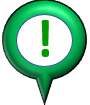** ATTENTION:  **When you run the model look at the scope **COMPARE_POS** scope.  

- It shows the time responses of our 7-dof AND also the ground displacements $\left(U_{\textrm{bRG}} \;\;,U_{\textrm{fRG}} \;\;,U_{\textrm{bLG}} \;\;,U_{\textrm{fLG}} \right)$

- For each dof plot, we show the Brain derived model response (in multi color) AND we've superimposed the corresponding response from the Simscape model in blue. 

 **CONCLUSION:**  The two models produce very similar results.